# Kinematic DH Parameters for 3-link RPR arm

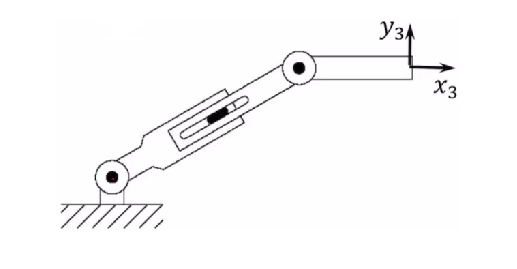

imshow(imread("./figures/RPR.png"))

### Robot Description

- **{r, p, r} : **r for revolute, p for prismatic

- **{0, 0, L_1} : **radius lenghts

- **{Pi/2, -Pi/2, 0} :** link twists

- **{0, q_2, 0} : **link offset rotation

- **{q1, 0, q3} : **joint rotation

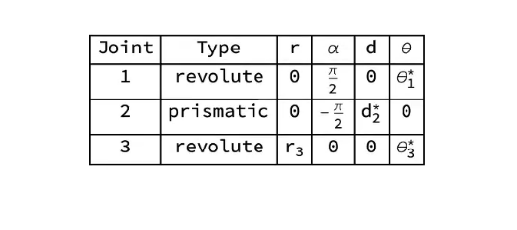

imshow(imread("./figures/DH.png"))

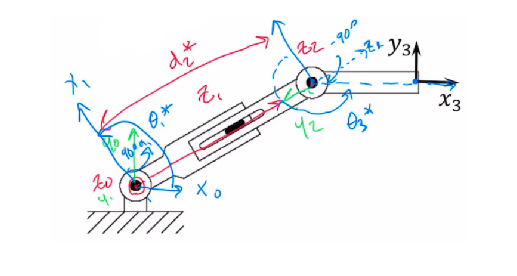

imshow(imread("./figures/annotated_RPR.png"))

The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- *A* — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- *α* — Angle of rotation for the common normal

- *d* — Offset along the *z*-axis in the normal direction, from parent to child

- *θ* — Angle of rotation for the *x*-axis along the previous *z*-axis


$$A_i ={\textrm{Rot}}_{z,\theta_i } {\textrm{Trans}}_{z,d_i } {\textrm{Trans}}_{x,\alpha_i } {\textrm{Rot}}_{x,\alpha_i }$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i }  & 0 & 0\\
s_{\theta_i }  & c_{\theta_i }  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & \alpha_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 1 & 0\\
0 & c_{\alpha_i }  & -s_{\alpha_i }  & 0\\
0 & s_{\alpha_i }  & c_{\alpha_i }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } c_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- $A$ — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- $\alpha$ — Angle of rotation for the common normal

- $d$ — Offset along the *z*-axis in the normal direction, from parent to child

- $\theta$ — Angle of rotation for the *x*-axis along the previous *z*-axis

Specify the parameters for the system as a matrix. Values come from .

t1 = 0 ;
d2 = 0 ; 
r3 = 0.1 ; % in cm
t3 = 0  ;

dhparams = [0   	 pi/2	    0   	t1 ;
            0	    -pi/2       d2      0  ;
            r3	     0	        0	    t3 ];

Create a rigid body tree object.

robot = rigidBodyTree;

Create a cell array for the rigid body object, and another for the joint objects. Iterate through the DH parameters performing this process:

- Create a `rigidBody` object with a unique name.

- Create and name a revolute `rigidBodyJoint` object.

- Use `setFixedTransform` to specify the body-to-body transformation of the joint using DH parameters. The function ignores the final element of the DH parameters, `theta`, because the angle of the body is dependent on the joint position.

- Use `addBody` to attach the body to the rigid body tree.

bodies = cell(3,1);
joints = cell(3,1);

bodies{1} = rigidBody(['body' num2str(1)]);
joints{1} = rigidBodyJoint(['jnt' num2str(1)],"revolute");
setFixedTransform(joints{1},dhparams(1,:),"dh");
bodies{1}.Joint = joints{1};
addBody(robot,bodies{1},"base")

bodies{2} = rigidBody(['body' num2str(2)]);
joints{2} = rigidBodyJoint(['jnt' num2str(2)],"prismatic");
setFixedTransform(joints{2},dhparams(2,:),"dh");
bodies{2}.Joint = joints{2};
addBody(robot,bodies{2},bodies{1}.Name)

bodies{3} = rigidBody(['body' num2str(3)]);
joints{3} = rigidBodyJoint(['jnt' num2str(3)],"revolute");
setFixedTransform(joints{3},dhparams(3,:),"dh");
bodies{3}.Joint = joints{3};
addBody(robot,bodies{3},bodies{2}.Name)



Verify that your robot has been built properly by using the `showdetails` or `show` function. The `showdetails` function lists all the bodies of the robot in the MATLAB® command window. The `show` function displays the robot with a specified configuration (home by default).

showdetails(robot)

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2    prismatic            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   
--------------------


figure(Name="RPR")
show(robot);

## Interact with Robot Model

Visualize the robot model to confirm its dimensions by using the `interactiveRigidBodyTree` object. 

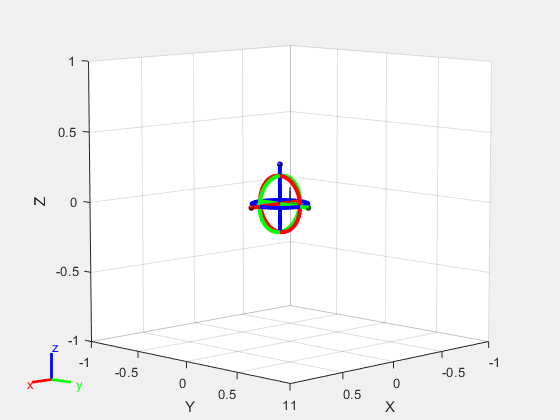

figure(Name="Interactive GUI")
gui = interactiveRigidBodyTree(robot,MarkerScaleFactor=1);

Click and drag the marker in the interactive GUI to reposition the end effector. The GUI uses inverse kinematics to solve for the joint positions that achieve the best possible match to the specified end-effector position. Right-click a specific body frame to set it as the target marker body, or to change the control method for setting specific joint positions.

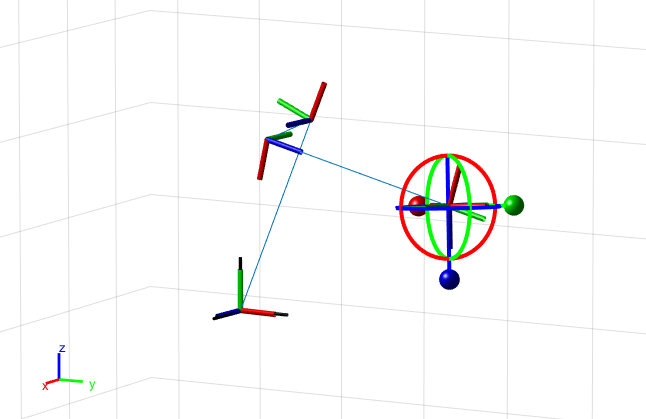

## Next Steps

Now that you have built your model in MATLAB®, these are some possible next steps.

- Perform [inverse kinematics](docid:robotics_doccenter#mw_533ce698-c4bd-430c-8cb9-add59bd96640) to get joint configurations based on desired end-effector positions. Specify robot constraints in addition to those of the model parameters, including aiming constraints, Cartesian bounds, and pose targets.

- [Trajectory Generation and Following](docid:robotics_doccenter#mw_d5333cca-a634-4d69-9ff5-1e99b99ab0e4), based on waypoints and other parameters, with trapezoidal velocity profiles, B-splines, or polynomial trajectories.

- Peform [Manipulator Motion Planning](docid:robotics_doccenter#mw_87184aa9-6b29-46a6-a396-aab126d8274f) utilizing your robot models and a rapidly-exploring random tree (RRT) path planner.

- Use [Collision Detection](docid:robotics_doccenter#mw_d93555e3-d6a3-4974-9088-680f8c5845f3) with obstacles in your environment to ensure safe and effective motion for your robot.

## References

[1] Corke, P. I., and B. Armstrong-Helouvry. “A Search for Consensus Among Model Parameters Reported for the PUMA 560 Robot.” *Proceedings of the 1994 IEEE International Conference on Robotics and Automation*, 1608–13. San Diego, CA, USA: IEEE Comput. Soc. Press, 1994. https://doi.org/10.1109/ROBOT.1994.351360.

*Copyright 2020 The MathWorks, Inc.*

clc
clear
close all


syms t1 d2 Xe Ye ;

dhparams = [0   	 pi/2	    0   	t1 ;
            0	    -pi/2       d2      0  ;
            10	     0	        0	    pi-t1 ];


H0_1 = DH(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4))

$$H0\_1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & 0 & \sin\left(t_{1}\right) & 0\\ \sin\left(t_{1}\right) & 0 & -\cos\left(t_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H1_2 = DH(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4))

$$H1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H2_3 = DH(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4))

$$H2\_3 = \left(\begin{array}{cccc} -\cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & -10\,\cos\left(t_{1}\right)\\ \sin\left(t_{1}\right) & -\cos\left(t_{1}\right) & 0 & 10\,\sin\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H0_2 = H0_1*H1_2

$$H0\_2 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & d_{2}\,\sin\left(t_{1}\right)\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_3 = H0_1*H1_2*H2_3

$$H0\_3 = \left(\begin{array}{cccc} -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & 0 & -10\,{\cos\left(t_{1}\right)}^{2}-10\,{\sin\left(t_{1}\right)}^{2}+d_{2}\,\sin\left(t_{1}\right)\\ 0 & -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O1_x = simplify(H0_1(1,4))

$$O1\_x = 0$$

O1_y = simplify(H0_1(2,4))

$$O1\_y = 0$$


O2_x = simplify(H0_2(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O2_y = simplify(H0_2(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


O3_x = simplify(H0_3(1,4))

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

O3_y = simplify(H0_3(2,4))

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$


xeq = Xe == O3_x

$$xeq = \mathrm{Xe}=d_{2}\,\sin\left(t_{1}\right)-10$$

yeq = Ye == O3_y

$$yeq = \mathrm{Ye}=-d_{2}\,\cos\left(t_{1}\right)$$


S = solve([xeq yeq],[t1 d2])

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]



simplify(S.t1)

$$ans = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}+\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right) \end{array}\right)$$

simplify(S.d2)

$$ans = \left(\begin{array}{c} -\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}\\ \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100} \end{array}\right)$$



t_1 = simplify(S.t1)

$$t\_1 = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}+\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right) \end{array}\right)$$

d_2 = simplify(S.d2)

$$d\_2 = \left(\begin{array}{c} -\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}\\ \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100} \end{array}\right)$$



Xe = 10

Xe = 10

Ye = 30

Ye = 30



t_1 = eval(t_1)

t_1 =    -0.5880
    2.5536


d_2 = eval(d_2)

d_2 =   -36.0555
   36.0555


O1_x = simplify(H0_1(1,4))

$$O1\_x = 0$$

O1_y = simplify(H0_1(2,4))

$$O1\_y = 0$$


O2_x = simplify(H0_2(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O2_y = simplify(H0_2(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


O3_x = simplify(H0_3(1,4))

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

O3_y = simplify(H0_3(2,4))

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$


% t1 = deg2rad(180-104.511+90)
% t3 = deg2rad(90-(180-104.511))
% d2 = sqrt(20^2+30^2)

t1 = atan(3/2)+pi/2

t1 = 2.5536

d2 = sqrt(20^2+30^2)

d2 = 36.0555



t1 = t_1(2)

t1 = 2.5536

d2 = d_2(2)

d2 = 36.0555




O2_x = eval(O2_x)

O2_x = 20

O2_y = eval(O2_y)

O2_y = 30


O3_x = eval(O3_x)

O3_x = 10

O3_y = eval(O3_y)

O3_y = 30


clf
link1 = line([0,O1_x],[0,O1_y])

link1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 0]
              YData: [0 0]
              ZData: [1×0 double]

  Show all properties


link2 = line([O1_x, O2_x],[O1_y, O2_y])

link2 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 20]
              YData: [0 30]
              ZData: [1×0 double]

  Show all properties


link3 = line([O2_x, O3_x],[O2_y, O3_y])

link3 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [20 10]
              YData: [30 30]
              ZData: [1×0 double]

  Show all properties


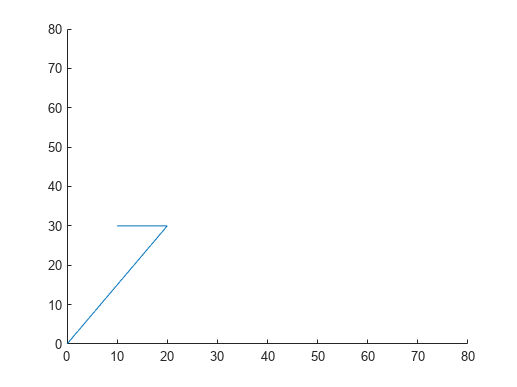

xlim([0 80])
ylim([0 80])

function [A] = DH(a,alpha,d,theta)

A = [cos(theta) -sin(theta)*round(cos(alpha))  sin(theta)*round(sin(alpha)) a*cos(theta);
     sin(theta)  cos(theta)*round(cos(alpha)) -cos(theta)*round(sin(alpha)) a*sin(theta);
     0           round(sin(alpha))             round(cos(alpha))            d ;
     0           0                             0                            1];
end